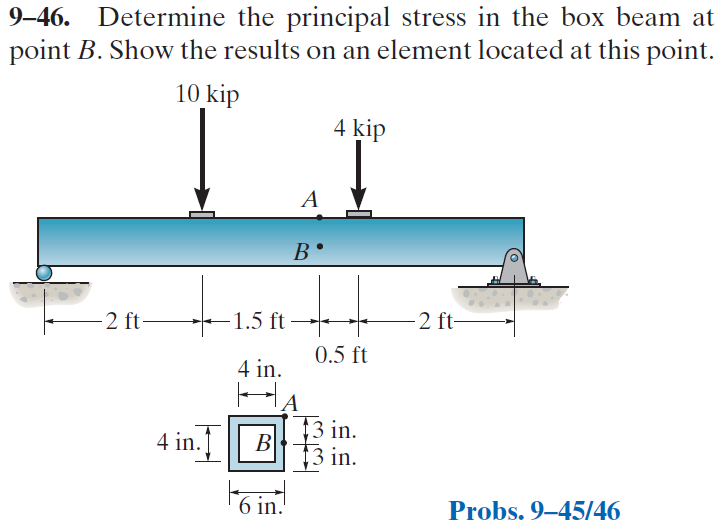

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-46P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-46P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('concentrated', 'force', -10*u.kip, 2*u.ft);
b = b.add('concentrated', 'force', -4*u.kip, 4*u.ft);
b = b.add('reaction', 'force', 'R2', 6*u.ft);
b.L = 6*u.ft;

# section properties

yc = [3/2; 2/2; -2/2; -3/2]*u.in;
Ac = [6*3; -4*2; -4*2; 6*3]*u.in^2;
Ic = [6*3^3; -4*2^3; -4*2^3; 6*3^3]*u.in^4/12;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{20736\,x\,\left(22\,{\mathrm{ft}}^{2}-x^{2}\right)}{65\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 2\,\mathrm{ft}\\ -\frac{5184\,\left(x^{3}-30\,x^{2}\,\mathrm{ft}+148\,x\,{\mathrm{ft}}^{2}-40\,{\mathrm{ft}}^{3}\right)}{65\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ -\frac{5184\,\left(x-6\,\mathrm{ft}\right)\,\left(3\,x^{2}-36\,x\,\mathrm{ft}+28\,{\mathrm{ft}}^{2}\right)}{65\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }4\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{20736\,\left(22\,{\mathrm{ft}}^{2}-3\,x^{2}\right)}{65\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }x\leq 2\,\mathrm{ft}\\ -\frac{5184\,\left(3\,x^{2}-60\,x\,\mathrm{ft}+148\,{\mathrm{ft}}^{2}\right)}{65\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ -\frac{5184\,\left(9\,x^{2}-108\,x\,\mathrm{ft}+244\,{\mathrm{ft}}^{2}\right)}{65\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{4}} & \text{ if }4\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 8\,x\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ -2\,\left(x-10\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ -6\,\left(x-6\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }4\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 8\,\mathrm{kip} & \text{ if }x\leq 2\,\mathrm{ft}\\ -2\,\mathrm{kip} & \text{ if }x\in \left(2\,\mathrm{ft},4\,\mathrm{ft}\right]\\ -6\,\mathrm{kip} & \text{ if }4\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} R_{1} & 8\,\mathrm{kip}\\ R_{2} & 6\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

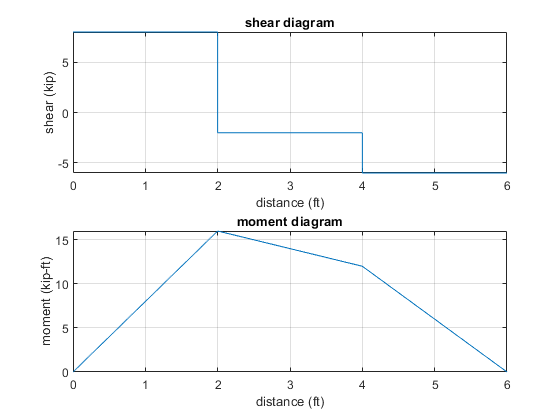

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# loads at point B

M = m(3.5*u.ft)

$$M = 13\,\mathrm{ft}\,\mathrm{kip}$$

V = v(3.5*u.ft)

$$V = -2\,\mathrm{kip}$$

# stresses at point B

% ----------------
% - bending stress
% ----------------
b.I = rewrite(b.I, u.in);
sigma_bending = sym(0)

$$sigma\_bending = 0$$

% --------------
% - shear stress
% --------------
Q = sum(Qn(1:2));
t = 2*u.in;
tau_shear = rewrite(-V*Q/(b.I*t), u.psi);
tau_shear_vpa = vpa(tau_shear, 5) %#ok<NASGU> 

$$tau\_shear\_vpa = 219.23\,\mathrm{psi}$$

# mohr stresses at point B

sigmax = sigma_bending

$$sigmax = 0$$

sigmay = sym(0)

$$sigmay = 0$$

tauxy = tau_shear;
tauxy_vpa = vpa(tauxy, 5) %#ok<NASGU> 

$$tauxy\_vpa = 219.23\,\mathrm{psi}$$

[sigmaxp sigmayp tauxyp thetap] = beam.principal(sigmax, sigmay, tauxy);
[sigmaxs sigmays tauxys thetas] = beam.max_shear(sigmax, sigmay, tauxy);

# mohr's circle for point B

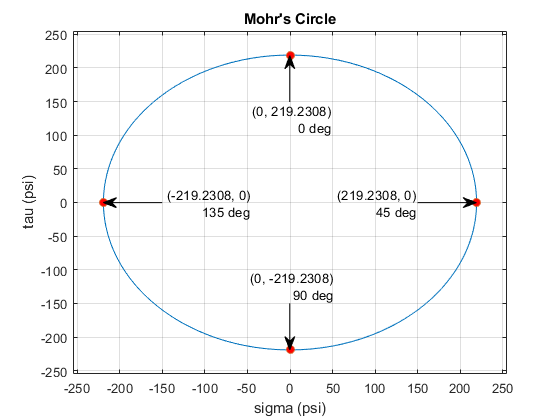

beam.mohr_plot(sigmax, sigmay, tauxy, {'psi'});
axis([-255 255 -255 255])
xvals = double(separateUnits([sigmaxp sigmaxs]));
yvals = double(separateUnits([tauxyp tauxys]));
thetavals = double(separateUnits([thetap thetas]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = 150;
      y1 = 0;
    case 2
      x1 = -150;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 150;
    case 4
      x1 = xvals(4);
      y1 = -150;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear tau_shear_vpa;
clear tauxy_vpa;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;